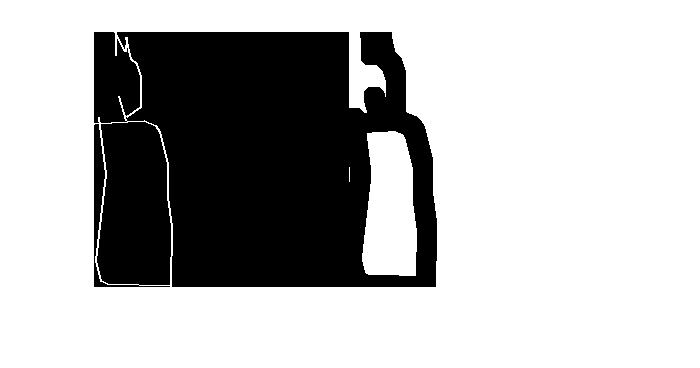

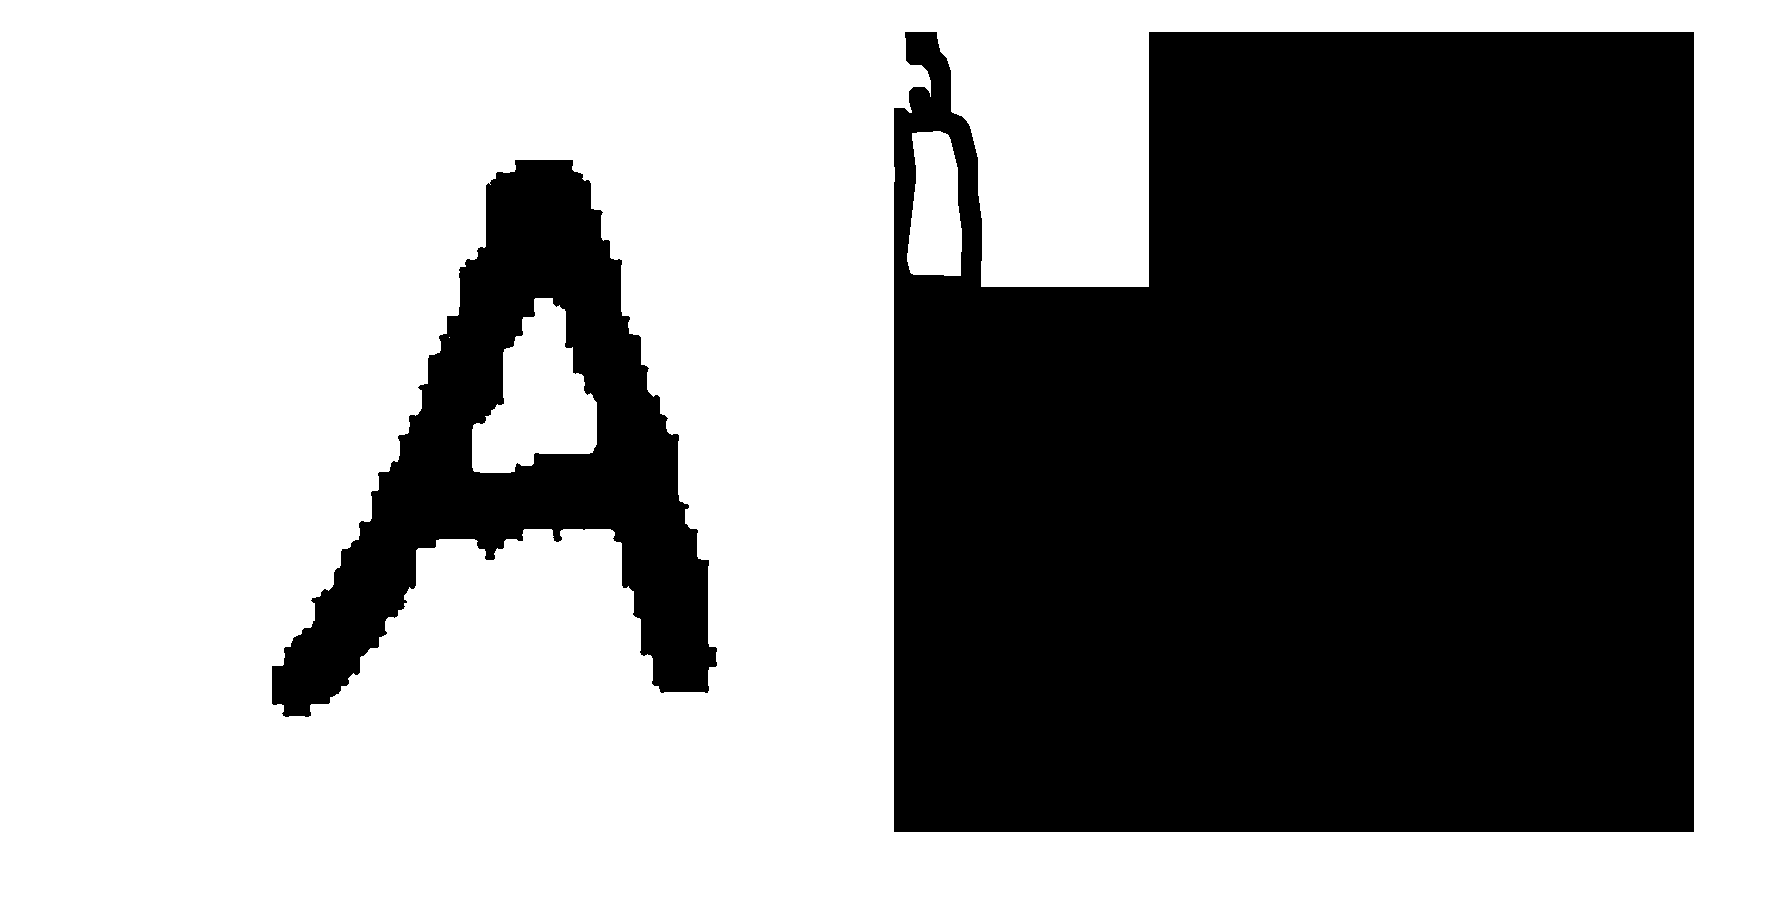

data3 = imread('D:\桌面\新建文件夹 (3)\8091.png');

data4 = imresize(data3, [800, 800], 'nearest');  % 'nearest', 'bilinear', 'bicubic'
data5 = imresize(data3, [800, 800], 'bilinear');
data6 = imresize(data3, [800, 800], 'bicubic');
figure
imshowpair(data3, data4, 'montage');
figure
imshowpair(data3, data5, 'montage');
figure
imshowpair(data3, data6, 'montage');

path1 = 'D:\桌面\新建文件夹 (4)';
path2 = 'D:\桌面\新建文件夹 (5)';
file = dir(fullfile(path1, '\', '*.png'));

for i = 1 : size(file, 1)
    
    filepathname = append(file(i).folder , '\', file(i).name);
    data1 = imread(filepathname);
    filepathnewname = append(path2, '\', 'image_', num2str(i), '.png');
    imwrite(data1, filepathnewname);
    
end

path1 = 'D:\桌面\新建文件夹 (2)';
path2 = 'D:\桌面\新建文件夹 (2)';
file = dir(fullfile(path1, '\', '*.png'));

for i = 1 : size(file, 1)
    
    filepathname = append(file(i).folder , '\', file(i).name);
    data1 = imread(filepathname);
    if numel(size(data1)) == 3
        data1 = rgb2gray(data1);
    end
    data2 = imresize(data1, [512 ,512]);
    filepathnewname = append(path2 , '\', file(i).name);
    imwrite(data2, filepathnewname);
    
end

file_path1 = 'D:\桌面\新建文件夹 (2)';
file_path2 = 'D:\桌面\新建文件夹';
img_path_list =  dir(strcat(file_path1, '\', '*.png'));
img_num = length(img_path_list);
if img_num > 0
    for i = 1 : img_num
        filepathname = strcat(file_path1, '\', img_path_list(i).name);
        headdata1 = imread(filepathname);
        if numel(size(headdata1)) == 3
            headdata1 = rgb2gray(headdata1);
        end
%         figure
%         imshow(headdata1)
        headdata2 = headdata1;
        [a1, b1, L1 ,L2 ,L3] = FindSidePoint(headdata2);
        headdata3 = imcrop(headdata2, [a1, b1, L1 ,L2]);  
%         figure
%         imshow(headdata3)
        L4 = floor(1.35*L3);
        headdata4=uint8(255*ones(L4));
        headdata4(floor(L4/2 - L2/2) : floor(L4/2 + L2/2), floor(L4/2 - L1/2) : floor(L4/2 + L1/2)) = headdata3;
%         figure
%         imshow(headdata4)
        headdata5 = imbinarize(imresize(headdata4, [800 800]));
%         figure
%         imshow(headdata5)
        filepathnewname = strcat(file_path2, '\', img_path_list(i).name);
        imwrite(headdata5 , filepathnewname);
    end
else
    disp('路径中不存在指定格式数据');
end

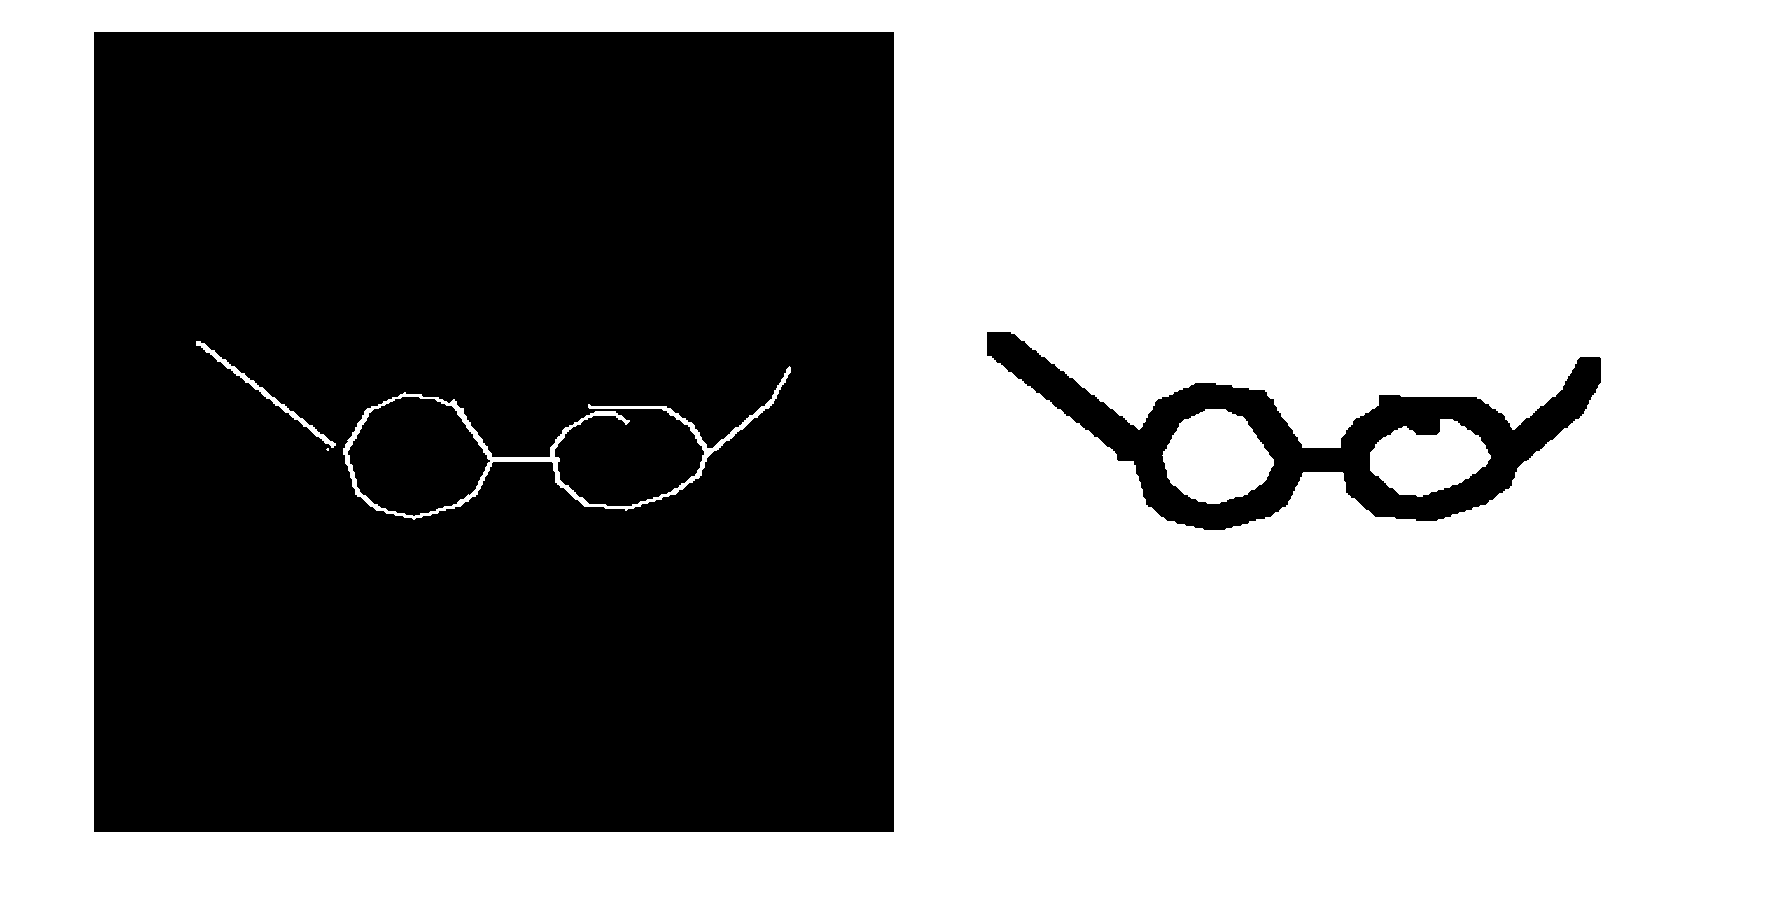


data1 = 1 - imread('D:\桌面\新建文件夹\image_1.png');
se = strel('square', 20');
data2 = 1 - imdilate(data1, se);
figure;imshowpair(data1, data2, 'montage');

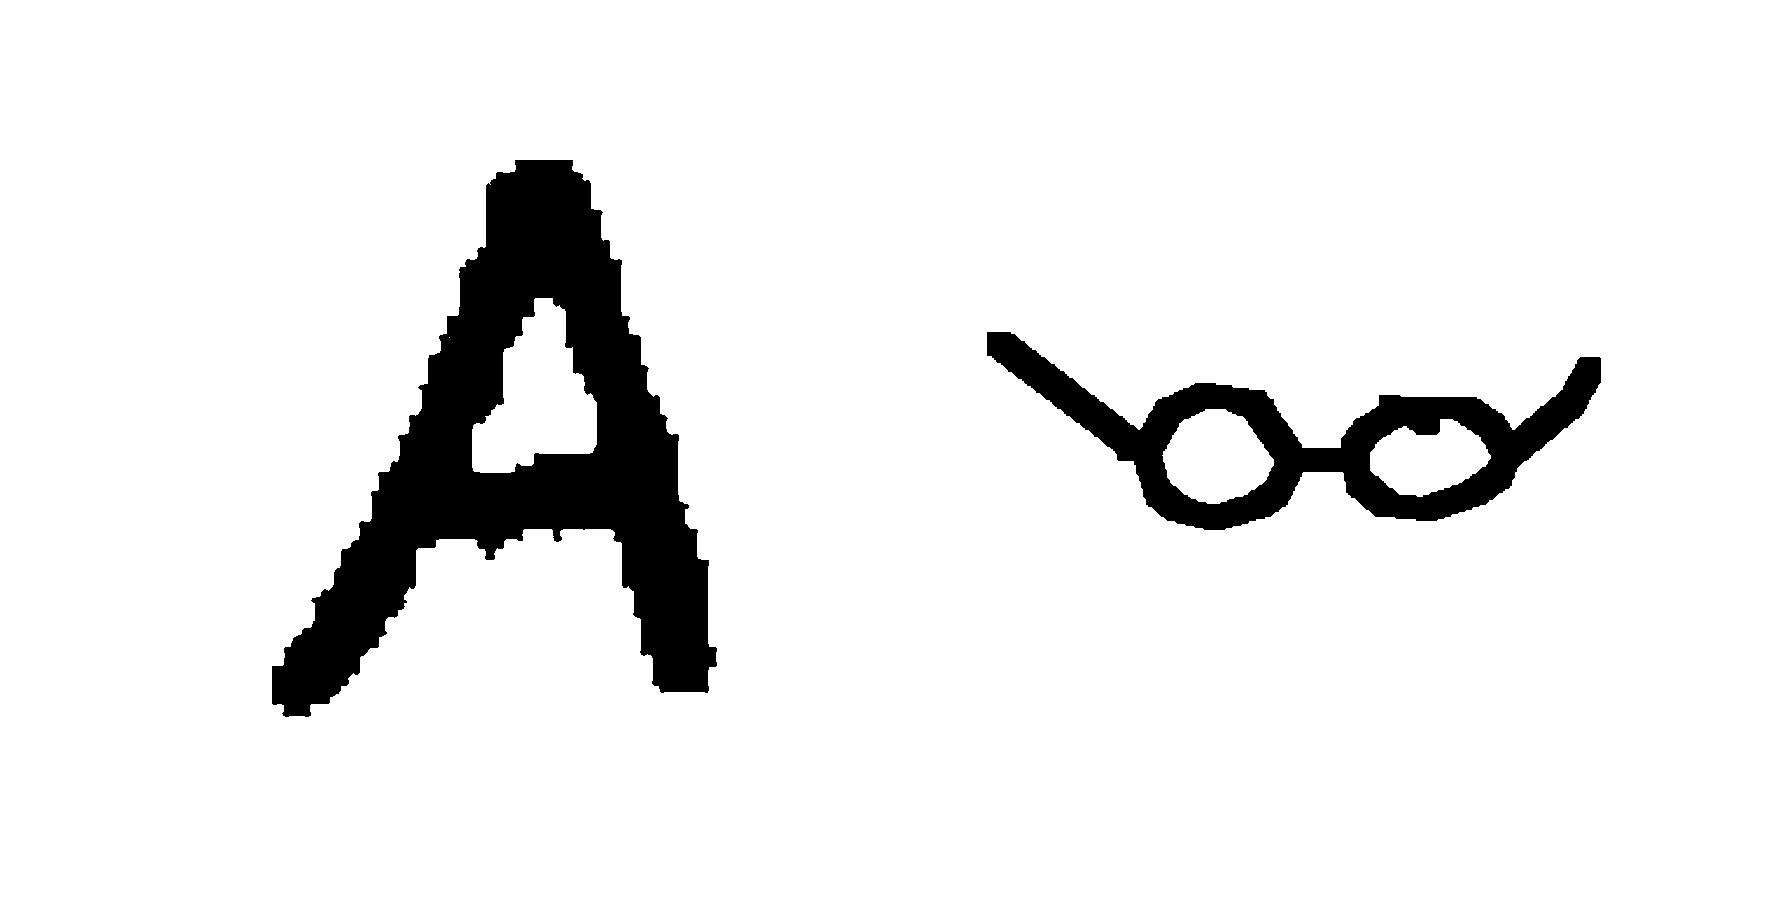

figure;imshowpair(imread('D:\桌面\新建文件夹 (3)\新建文件夹 (3)\a.png'), data2, 'montage');

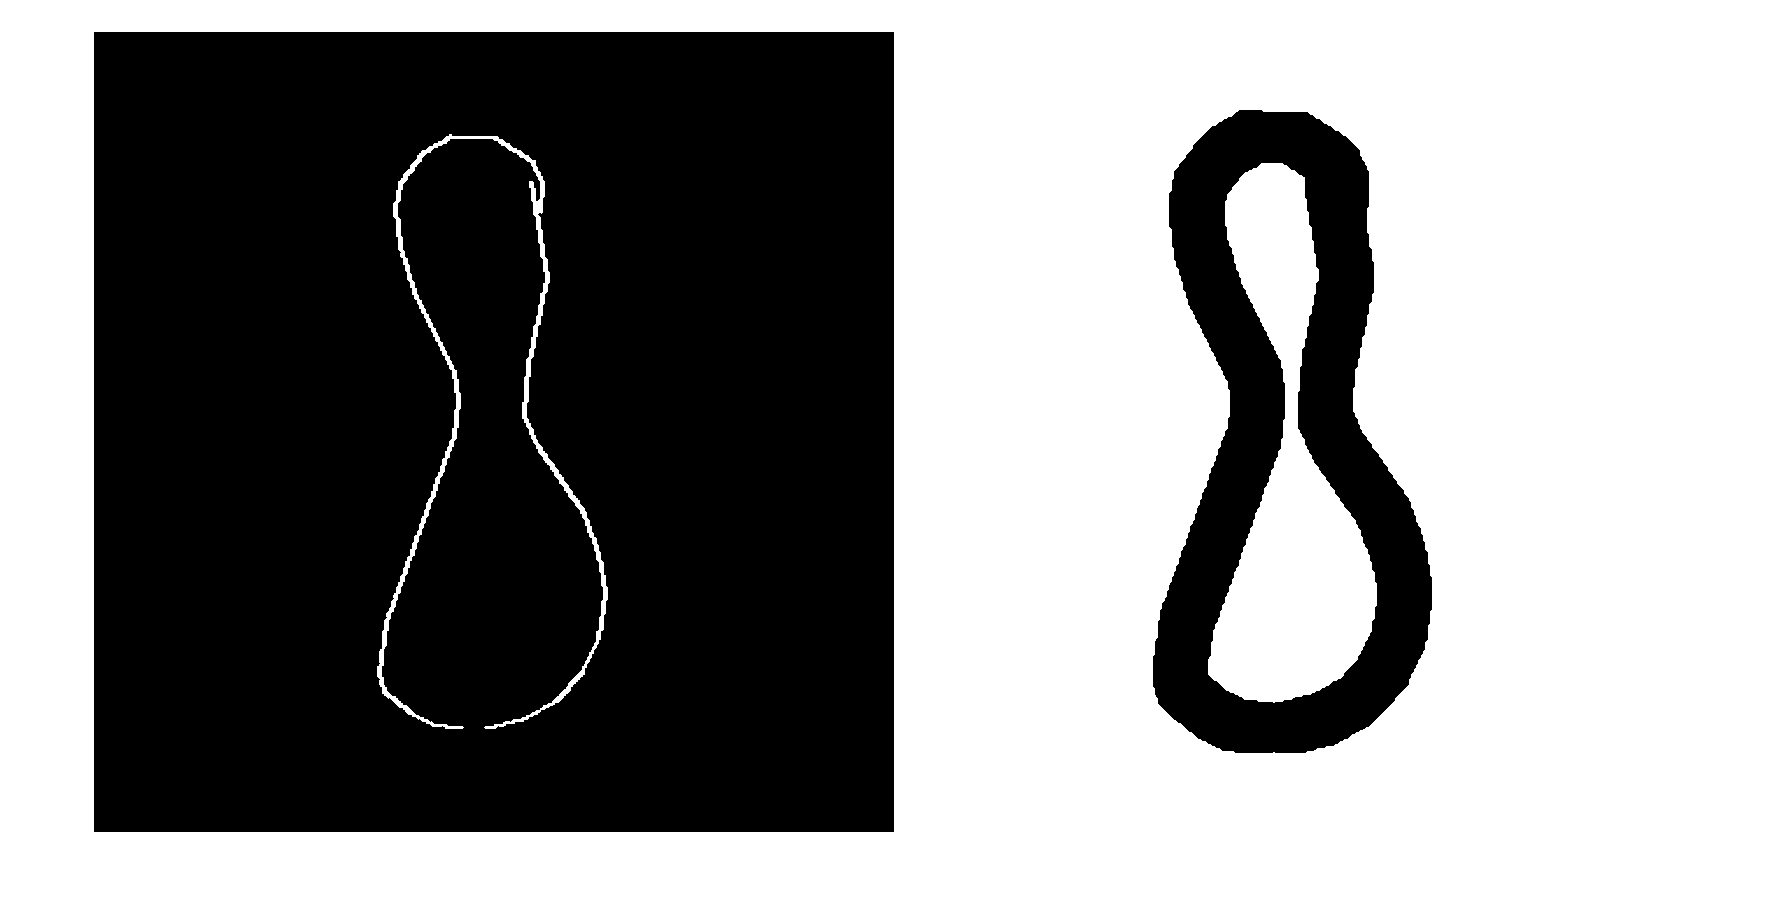

data1 = 1 - imread('D:\桌面\新建文件夹\image_36.png');
se = strel('disk', 25');
data2 = 1 - imdilate(data1, se);
figure;imshowpair(data1, data2, 'montage');

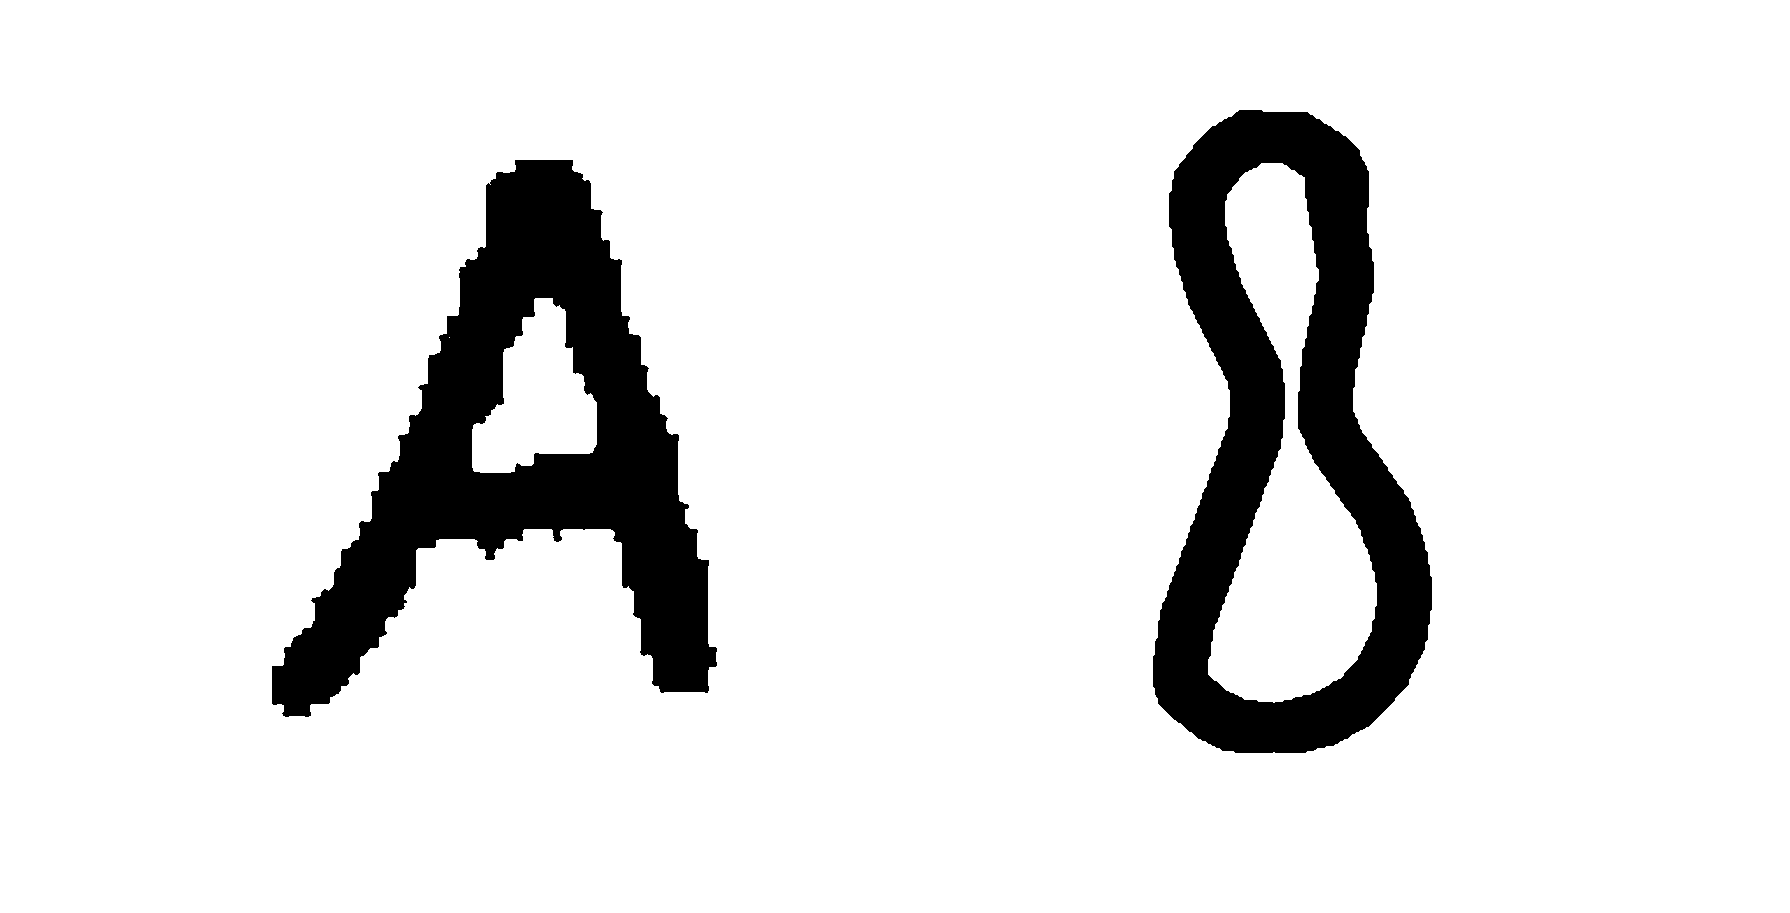

figure;imshowpair(imread('D:\桌面\新建文件夹 (3)\新建文件夹 (3)\a.png'), data2, 'montage');

file_path1 = 'D:\桌面\新建文件夹';
file_path2 = 'D:\桌面\QuickDraw_Process';
img_path_list =  dir(strcat(file_path1, '\', '*.png'));
img_num = length(img_path_list);
for i = 1 : img_num
    filepathname = strcat(img_path_list(i).folder, '\', img_path_list(i).name);
    data1 = imread(filepathname);
    data2 = 1 - data1;
    se = strel('disk', 25');
    data3 = 1 - imdilate(data2, se);
    filepathnewname = strcat(file_path2, '\', img_path_list(i).name);
    imwrite(data3 , filepathnewname);
end

clear; clc;
train_pre_namelist=dir('D:\桌面\QuickDraw_Process_2\*.png');
Grating = double(imread('D:\桌面\工作\数据\光栅\光栅1.png'));
Num = size(train_pre_namelist, 1);
s=800;

for i = 1 : Num
    
    listname = train_pre_namelist(i).name;
    listpath = train_pre_namelist(i).folder;
    Image = double(imbinarize(imread([listpath, '/', listname])));
%     Image = 1 - Image;
    Image = imresize(Image, [s, s]);
    Image1 = ones(1200, 1920);
    Image1(600-s/2+1:600+s/2,960-s/2+1:960+s/2) = Image;
    Image2 = (1-Image1).*Grating;
    Image3 = Image2;
    
    for m=1:1200
        for n=1:1920
            if Image2(m,n)>255
                Image3(m,n)=Image3(m,n)-256;
            end
        end
    end
    
    Image = uint8(Image3);
    imwrite(Image,['D:\桌面\QuickDraw_Process_3\', listname])
    
end
